## 1) Randomly select an IR image for testing

clear; clc;clf;
% repeat sample folder, no need to execute the previous cell
flir_dir = [pwd '\FLIR-samples\'];
ir_imgs = dir(flir_dir);

% local random test, speed performance evaluation
% img = randsample(ir_imgs(3:end), 1);
img = ir_imgs(6);
A = imread([flir_dir, img.name]);
[~,~,c] = size(A);
if c==1
    Im = im2double(A);
else
    Im = im2double(rgb2gray(A));
end
disp('Stylized Edge Extraction:')

Stylized Edge Extraction:


tic;
r1 = 1;
r2 = 3;
n = 16;
seog = stylized_edge_og(Im,r1, r2,n);
toc;

历时 0.160515 秒。


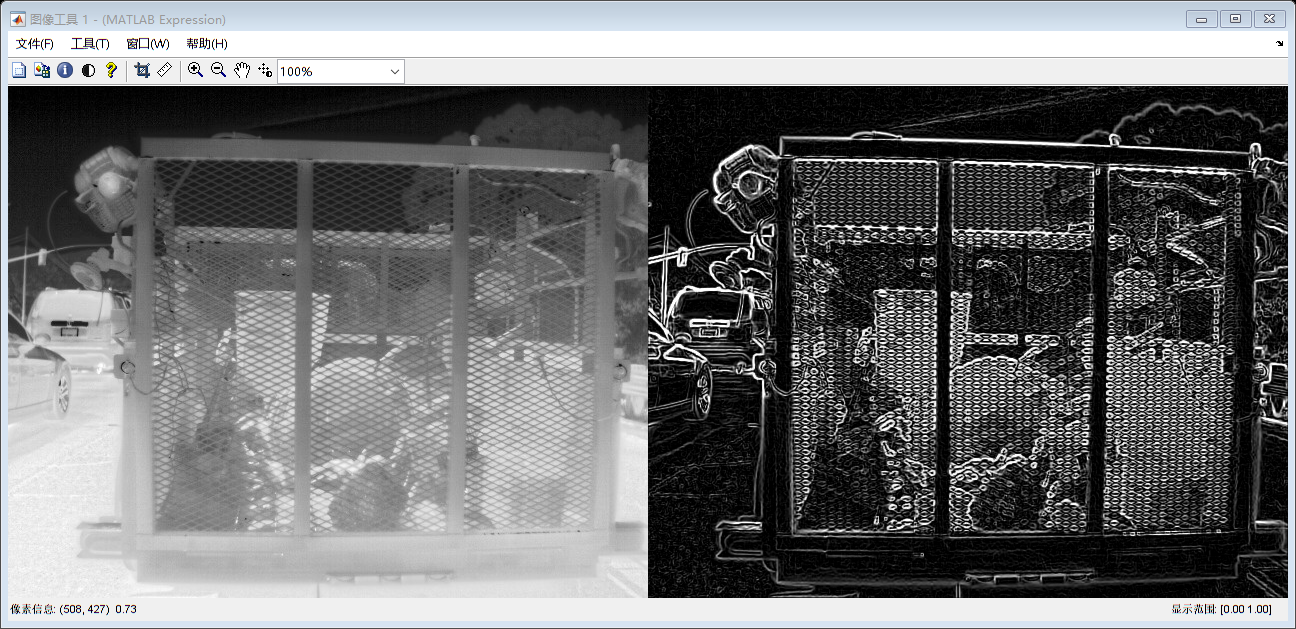

imtool([Im seog]);

## 2) Randomly select a batch of IR images for testing

clear; clc;clf;

flir_dir = [pwd '\FLIR-samples\'];
ir_imgs = dir(flir_dir);
% batch number
N = 5;
ba_imgs = randsample(ir_imgs(3:end),N);

bse_dir = '.\FLIR-batch-results\';
if ~exist(bse_dir, "dir")
    mkdir(bse_dir);    
end
delete([bse_dir '*.jpeg']);

% Stylized edge extraction time
t1 = zeros(1,N); 
% Save the adptive threshold
tha = cell(1,N);

% Canny edge execution time
t2 = zeros(1,N);
% Save the hard-coded threshold, in Canny, lowthreshold = 0.4 * highthreshold,
% and manually set the non-edge percentage to 70%.
ths = cell(1,N);

for i=1:N
    I = im2double(imread([flir_dir, ba_imgs(i).name]));
    tic;
    [seog, lth] = stylized_edge_og(I,2);
    t1(i) = toc;
    tha{i} = lth;
    % Save result image
    imwrite(seog, [bse_dir 'se-' ba_imgs(i).name]);
    tic;
    [ec,th] = edge(I, 'Canny');
    ths{i} = th;
    t2(i) = toc;
    imwrite(ec, [bse_dir 'ec-' ba_imgs(i).name]);
end

% Average time
tm1 = sum(t1)/N;
disp(['SEOG: Average time of ', num2str(N), ' images:', num2str(tm1)]);

SEOG: Average time of 5 images:0.12014



tm2 = sum(t2)/N;
disp(['Canny: Average time of ', num2str(N), ' images:', num2str(tm2)]);

Canny: Average time of 5 images:0.035515


## 3) Process all sample images and count the average execution time

clear; clc;clf;
% repeat sample folder, no need to execute the previous cell
flir_dir = [pwd '\FLIR-samples\'];
ir_imgs = dir(flir_dir);
N = length(ir_imgs);

se_dir = '.\FLIR-stylized-edges\';
if ~exist(se_dir, "dir")
    mkdir(se_dir);    
end
delete([se_dir '*.jpeg']);

% Stylized edge extraction time
t1 = zeros(1,N-2); 
% Save the adptive threshold
tha = cell(1,N-2);

% Canny edge execution time
t2 = zeros(1,N-2);
% Save the hard-coded threshold, in Canny, lowthreshold = 0.4 * highthreshold,
% and manually set the non-edge percentage to 70%.
ths = cell(1,N-2);

for i=3:N
    I = im2double(imread([flir_dir, ir_imgs(i).name]));
    tic;
    [seog, lth] = stylized_edge_og(I,2);
    t1(i-2) = toc;
    tha{i-2} = lth;
    % Save result image
    imwrite(seog, [se_dir 'se-' ir_imgs(i).name]);
    tic;
    [ec,th] = edge(I, 'Canny');
    ths{i-2} = th;
    t2(i-2) = toc;
    imwrite(ec, [se_dir 'ec-' ir_imgs(i).name]);
end

% Average time
tm1 = sum(t1)/(N-2);
disp(['SEOG: Average time of ', num2str(N-2), ' images:', num2str(tm1)]);

SEOG: Average time of 30 images:0.22645



tm2 = sum(t2)/(N-2);
disp(['Canny: Average time of ', num2str(N-2), ' images:', num2str(tm2)]);

Canny: Average time of 30 images:0.06178


## 4) Image processing time at different scales

clear; clc;clf;
% repeat sample folder, no need to execute the previous cell
flir_dir = [pwd '\FLIR-samples\'];
ir_imgs = dir(flir_dir);

% Randomly choose 9 infrared images to compose a large image
imgs = randsample(ir_imgs(3:end), 9);
A = imread([flir_dir, imgs(1).name]);
[~,~,c] = size(A);
if c==1
    Im = im2double(A);
else
    Im = im2double(rgb2gray(A));
end

for i=2:9
    A = imread([flir_dir, imgs(i).name]);
    if c==1
        Im(:,:,i) = im2double(A);
    else
        Im(:,:,i) = im2double(rgb2gray(A));
    end
end

Ix = [Im(:,:,1) Im(:,:,2) Im(:,:,3);
      Im(:,:,4) Im(:,:,5) Im(:,:,6);
      Im(:,:,7) Im(:,:,8) Im(:,:,9);];

tic;
stylized_edge_og(Ix);
toc;

历时 1.198473 秒。


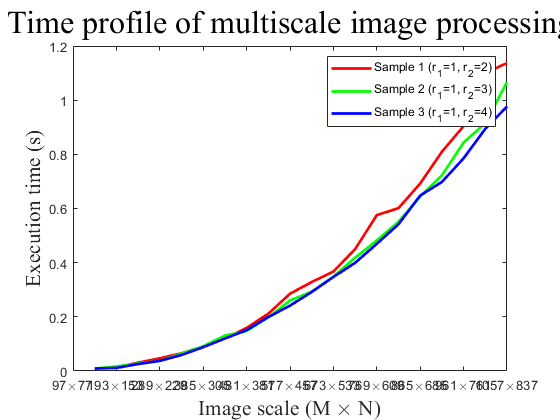


[h,w] = size(Ix);

% Center points of `Ix`
x0 = round((w+1)/2);
y0 = round((h+1)/2);

n = 20;
rxn = floor(w/n/2);
ryn = floor(h/n/2);

t1 = zeros(1,n);

for i=1:20
    Im = Ix(max(1,y0-i*ryn):min(y0+i*ryn,h), max(1,x0-i*rxn):min(x0+i*rxn,w));
    tic;
    stylized_edge_og(Im,1,2);
    t1(i) = toc;
end

plot(1:20,t1,'-r', 'LineWidth', 2);
hold on;

t2 = zeros(1,n);
for i=1:20
    Im = Ix(max(1,y0-i*ryn):min(y0+i*ryn,h), max(1,x0-i*rxn):min(x0+i*rxn,w));
    tic;
    stylized_edge_og(Im,1,3);
    t2(i) = toc;
end
plot(1:20,t2,'-g', 'LineWidth', 2);

t3 = zeros(1,n);
xts = cell(1,n);
for i=1:20
    Im = Ix(max(1,y0-i*ryn):min(y0+i*ryn,h), max(1,x0-i*rxn):min(x0+i*rxn,w));
    sz = size(Im);
    xts{i} = [num2str(sz(2)) '\times' num2str(sz(1))];
    tic;
    stylized_edge_og(Im,1,4);
    t3(i) = toc;
end
plot(1:20,t3,'-b', 'LineWidth', 2);

title('Time profile of multiscale image processing', ...
    'FontSize', 24, ...
    'FontName', 'Times New Roman');
xlabel('Image scale (M \times N)', ...
    'FontSize', 16, ...,
    'FontName', 'Times New Roman');
xticklabels(xts);
ylabel('Execution time (s)', ...
    'FontSize', 16, ...,
    'FontName', 'Times New Roman');
legend('Sample 1 (r_1=1, r_2=2)', 'Sample 2 (r_1=1, r_2=3)', 'Sample 3 (r_1=1, r_2=4)');

hold off;

## 5) Test on Color image from FLIR dataset

clear; clc;clf;

rgb_dir = [pwd '\RGB\'];
imgs = dir(rgb_dir);
delete([rgb_dir 'se-*.jpg']);

% Randomly choose 1 color images to test
img = randsample(imgs(3:end), 1);
A = imread([rgb_dir img.name]);

% [~,n] = max([std2(A(:,:,1)), std2(A(:,:,2)), std2(A(:,:,3))]);
% I = im2double(A(:,:,n));

I = im2double(rgb2gray(A));

tic;
seog = stylized_edge_og(I);
toc;

历时 1.252695 秒。


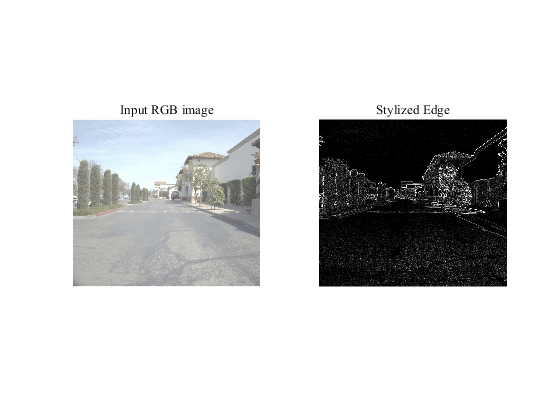


% save results
imwrite(seog, [rgb_dir 'se-' img.name]);

% imtool([I seog]);

figure("Name", "Show the compared results");
subplot(1,2,1);
imshow(A);
title('Input RGB image', 'FontName', 'Times New Roman');
subplot(1,2,2);
imshow(seog);
title('Stylized Edge', 'FontName', 'Times New Roman');

## 6) Test on Color image from [BSDS500](http://www.eecs.berkeley.edu/Research/Projects/CS/vision/grouping/BSR/BSR_bsds500.tgz) 

clear; clc;clf;

rgb_dir = [pwd '\BSDS500-samples\'];
imgs = dir(rgb_dir);

% Randomly choose 1 color images to test
img = randsample(imgs(3:end-1), 1);
img = imgs(6);
name = img.name;
A = imread([rgb_dir name]);

% RGB to gray
I = im2double(rgb2gray(A));

tic;
seog = stylized_edge_og(I);
toc;

历时 0.083581 秒。


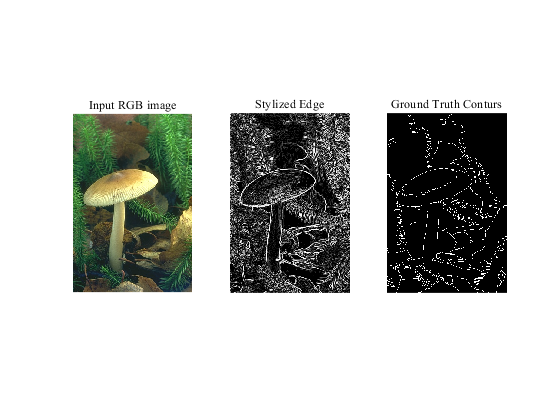


% load ground truth contours map to compare
load([rgb_dir 'groundTruth\' name(1:end-4) '.mat']);

% choose the most detailed Boundaries
[~, m] = max([mean2(groundTruth{1}.Boundaries) ...
    mean2(groundTruth{2}.Boundaries) ...
    mean2(groundTruth{3}.Boundaries) ...
    mean2(groundTruth{4}.Boundaries) ...
    mean2(groundTruth{5}.Boundaries)]);

% save results
% imwrite(seog, [rgb_dir 'se-' name]);
% imwrite(groundTruth{m}.Boundaries, [rgb_dir 'gt-' name]);

% Show compared images
% imtool([seog groundTruth{m}.Boundaries]);
figure("Name", "Show the compared results");
subplot(1,3,1);
imshow(A);
title('Input RGB image', 'FontName', 'Times New Roman');

subplot(1,3,2);
imshow(seog);
title('Stylized Edge', 'FontName', 'Times New Roman');

subplot(1,3,3);
imshow(groundTruth{m}.Boundaries);
title('Ground Truth Conturs', 'FontName', 'Times New Roman');

## Compared to classical edge extraction methods

generate image for `Fig.5`

% Generate the images for `Fig.5` in the article

demo_img = 'Fig5_a.png';
% demo_img = 'Test_vector.png';
Im = im2double(rgb2gray(imread(demo_img)));
es = stylized_edge_og(Im,3);

% save folder
save_dir = '.\Fig5\';
if ~exist(save_dir, "dir")
    mkdir(save_dir);
end
delete([save_dir '*.png']);

imwrite(Im, [save_dir 'Fig5_a.png']);

ec1 = edge(Im,'Canny', [0.02,0.05]);
imwrite(ec1, [save_dir 'Fig5_b.png']);
ec2 = edge(Im,'Canny',[0.01 0.03]);
imwrite(ec2, [save_dir 'Fig5_c.png']);

ec3 = edge(Im, 'Sobel', 0.01);
imwrite(ec3, [save_dir 'Fig5_d.png']);

ec4 = edge(Im, 'Prewitt', 0.01);
imwrite(ec4, [save_dir 'Fig5_e.png']);

ec5 = edge(Im, 'Roberts', 0.01);
imwrite(ec5, [save_dir 'Fig5_f.png']);

imwrite(es, [save_dir 'Fig5_g.png']);

## Reselect a batch of images to test

Get sample images from FLIR thermal dataset

clear; clc;clf;
% sample number
sn = 30;

% Local FLIR sample images
flir_dir = '.\FLIR-samples\';
if ~exist(flir_dir, "dir")
    mkdir(flir_dir);    
end

% List all local sample images
ir_imgs = dir(flir_dir);
n = length(ir_imgs);

% confirm by user
answer = questdlg(['There are ', num2str(n-2), ...
    ' images in `FLIR-samples` folder, would you like to continue?'], ...
    'Reselect the sample images', ...
    'No', 'Yes', 'No');

switch answer
    case {'No',''}
        return;
    case 'Yes'
        confirm = true;
    otherwise
        confirm = false;
end

% If the number is insufficient, resample from the source 
% FLIR thermal datasets
if confirm
    % local FLIR thermal dataset file path in our PC
    FLIR_ROOT = 'F:\FLIR_ADAS_1_3\train\thermal_8_bit\';
    imgs = dir(FLIR_ROOT);
    assert(length(imgs)>3);
    % random sampling
    ir_imgs = randsample(imgs(3:end),sn);
    
    % Copy to local save directory
    delete([flir_dir '*.jpeg']);
    
    for i=1:sn    
        copyfile([FLIR_ROOT ir_imgs(i).name],flir_dir);
    end
end


## Draw average time profile

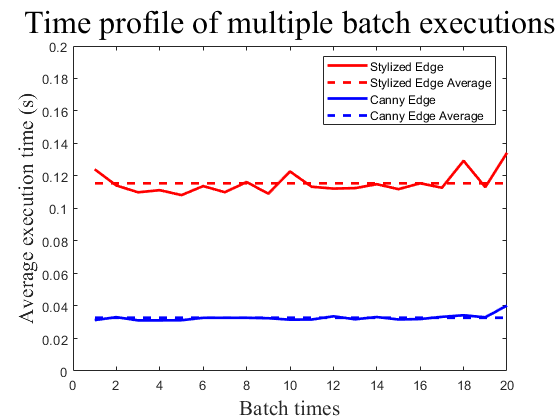

clear; clc;clf;

flir_dir = [pwd '\FLIR-samples\'];
ir_imgs = dir(flir_dir);

Batch = 20;
tm1 = zeros(1, Batch);
tm2 = zeros(1, Batch);

for j=1:Batch
    % batch number
    N = 5;
    ba_imgs = randsample(ir_imgs(3:end),N);
    
    % Stylized edge extraction time
    t1 = zeros(1,N); 
    
    % Canny edge execution time
    t2 = zeros(1,N);
    
    
    for i=1:N
        I = im2double(imread([flir_dir, ba_imgs(i).name]));
        tic;
        stylized_edge_og(I,3);
        t1(i) = toc;    
        
        tic;
        [ec,th] = edge(I, 'Canny');    
        t2(i) = toc;    
    end
    
    % Average time
    tm1(j) = sum(t1)/N;
    tm2(j) = sum(t2)/N;
end

tm1m = sum(tm1)/Batch*ones(1,Batch);
tm2m = sum(tm2)/Batch*ones(1,Batch);
plot(1:Batch, tm1, '-r', ...
    1:Batch, tm1m, '--r',...
    1:Batch, tm2, '-b', ...
    1:Batch, tm2m, '--b',...
    'LineWidth',2);

title('Time profile of multiple batch executions', ...
    'FontSize', 24, ...
    'FontName', 'Times New Roman');
xlabel('Batch times', ...
    'FontSize', 16, ...,
    'FontName', 'Times New Roman');
ylim([0 0.2]);
ylabel('Average execution time (s)', ...
    'FontSize', 16, ...,
    'FontName', 'Times New Roman');
legend('Stylized Edge', ...
    'Stylized Edge Average', ...
    'Canny Edge', ...
    'Canny Edge Average');